For den første kompressor GP18CB/SC21G

clear
T_1 = -20; %C
T_4 = -10; %C


%%%%%%%%%%%%%%          R134a        %%%%%%%%%%%%%%%%%%%%%
%                         R1

L = 7%sym('L', 'positive') %, 'positive'
% syms L

nu = 0.000001511; %m^2 / s

eta_1 = 0.00001022; %kg/(m*s)

q_m = 0.00338; %kg/s


d_1 = (9.52 - 2 * 0.8) / 1000 % m %indre diameter af kobber rør
g = 9.82; % m/s^2

lambda_1 = 0.01036 %[W/m-K]
r_fordamp = 211.2 * 1000% J/kg%m * l_fd
Re_1 = q_m * d_1 / (pi/4 * d_1^2 * eta_1)
K_f = r_fordamp / (L * g) 
NUs_1 = 0.0075 * (Re_1^2 * K_f )^0.40

alpha_1 = NUs_1 * lambda_1 / d_1;
alpha_1_ = vpa(alpha_1,5)

A_1 = pi*d_1*L

R_1 = vpa(1 / (alpha_1 * A_1), 3) % K/W
%%%%%%%%%%%%%%%%%%%%%  Kobber rør   %%%%%%%%%%%%%
%                         R2

r_1 = d_1/2 % m % indre radius
d_2 = 9.52 / 1000 % m ydre diamter af rør
r_2 = d_2 /2  % m % ydre radius

lambda_2 = 372; % W/(m*K) Tabel 10.11 i thermo bog version 4


R_2 = (r_2 / r_1) / (lambda_2 * 2 * pi * L)


%%%%%%%%%%%%%%%%%%%%    Brine  20% saltblanding NaCl  %%%%%%%%%%%%%%%%%
%                       R3

T_3 =  -18; % C gæt

nu_3 = 0.000003921; %[m^2/s]
c_p_3 = 3.354 * 1000; %[J/Kg * K]
rho_3 = 1162; % kg/m^3
lambda_3 = 0.5172; % W/(m*K)

a_3 = lambda_3 / (c_p_3 * rho_3)
beta_3 =  0.000021; %1/K  % chat bot


eta_3 = nu_3 * rho_3

%19l/min

s =  19 / (60 * 10 * 10 * 10); %pumpen  kan lever 19L/min
% min1/s60
% 1m^3/L1000
d_pumpe = 0.01; % m

d_brine1 = 0.18;
A_brine1 = pi * (d_brine1/2)^2;
d_brine2 = 0.20;
A_brine2 = pi * (d_brine2/2)^2;

% A_pumpe = A_brine2 - A_brine1
% A_pumpe = 0.06
A_pumpe = pi * (d_pumpe/2)^2

c = 0.5%s / A_pumpe %pga sug gange med 2

% c = 1

Re_3 = c / (pi/4 * d_2^2 * eta_3)
vpa(Re_3,6)


Pr_3 = eta_3 * c_p_3 / lambda_3
Pr_v3 = Pr_3
% NUs_3 = (0.60 + (0.387 * Ra^(1/6)) / (1 + (0.559/Pr_3)^(9/16))^(8/27) )^2
C_3 = 0.26;
m = 0.6;
n = 0.36;



NUs_3 = C_3 * Re_3^m * Pr_3^n * (Pr_3/Pr_v3)^(1/4)

alpha_3 = NUs_3 * lambda_3 / d_2 

A_3 = pi * d_2 * L

R_3 = 1 / (alpha_3 * A_3)

TOTAL udregninger

Phi_0 = 500%w 


R_tot_eq1 = R_1 + R_2  +  R_3 %+ R_3
R_tot_eq2 = (T_4 - T_1) / Phi_0


% L_fordamp = solve(R_tot_eq1 == R_tot_eq2, L)


For den nye kompressor GS34MFX

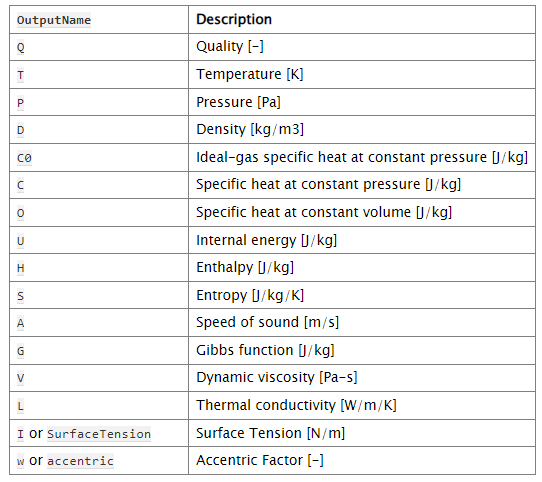

clear all
clf

% Importer CoolProp-modul
CoolProp = py.importlib.import_module('CoolProp.CoolProp');

% Stof (kan ændres efter behov)
fluid = 'R134a';

T_1 = -10 + 273.15 %K
T_4 = -20 + 273.15 %K
P_low = 1.33 * 1e5
h_1 = 389428;
h_4 = 241463;

%%%%%%%%%%%%%%          R134a        %%%%%%%%%%%%%%%%%%%%%
%                         R1

% L = 7%sym('L', 'positive') %, 'positive'
syms L
% L = 6.7 %m

% nu_1 =  CoolProp.PropsSI('V', 'P', P_low, 'T', T_1, fluid)%0.000001511; %m^2 / s
eta_4 =  CoolProp.PropsSI('V', 'Q', 0, 'T', T_4, fluid)
eta = eta_4 %(nu_1 + nu_4)/2

% rho_1 = CoolProp.PropsSI('D', 'T', T_1, 'P', P_low, fluid)
rho_4 = CoolProp.PropsSI('D', 'T', T_4, 'Q', 0, fluid)
rho = rho_4%(rho_1 + rho_4)/2

nu = eta / rho

% eta_1 = 0.00001022; %kg/(m*s)

q_m = 0.008497; %kg/s


d_1 = (9.52 - 2 * 0.8) / 1000 % m %indre diameter af kobber rør
g = 9.81; % m/s^2

% lambda_1 =  CoolProp.PropsSI('D', 'T', T_1, 'P', P_low, fluid)%0.01036 %[W/m-K]
lambda_4 =  CoolProp.PropsSI('L', 'T', T_4, 'Q', 0, fluid)
lambda = lambda_4

r_fordamp = 211.2 * 1000% J/kg%m * l_fd


Re_1 = q_m * d_1 / (pi/4 * d_1^2 * eta)

K_f = r_fordamp / (L * g) 

NUs_1 = 0.0075 * (Re_1^2 * K_f )^0.40

alpha_1 = NUs_1 * lambda / d_1;

alpha_1_ = vpa(alpha_1,5)

A_1 = pi*d_1*L

R_1 = vpa(1 / (alpha_1 * A_1), 3) % K/W
%%%%%%%%%%%%%%%%%%%%%  Kobber rør   %%%%%%%%%%%%%
%                         R2

r_1 = d_1/2 % m % indre radius
d_2 = 9.52 / 1000 % m ydre diamter af rør
r_2 = d_2 /2  % m % ydre radius

lambda_2 = 372; % W/(m*K) Tabel 10.11 i thermo bog version 4


R_2 = (r_2 / r_1) / (lambda_2 * 2 * pi * L)


%%%%%%%%%%%%%%%%%%%%    Brine  20% saltblanding NaCl  %%%%%%%%%%%%%%%%%
%                       R3


nu_3 = 0.000003921; %[m^2/s]
c_p_3 = 3.354 * 1000; %[J/Kg * K]
rho_3 = 1162; % kg/m^3
lambda_3 = 0.5172; % W/(m*K)

a_3 = lambda_3 / (c_p_3 * rho_3)
beta_3 =  0.000021; %1/K  % chat bot


eta_3 = nu_3 * rho_3

%19l/min

s =  19 / (60 * 10 * 10 * 10); %pumpen  kan lever 19L/min
% min1/s60
% 1m^3/L1000
d_pumpe = 0.01; % m

d_brine1 = 0.18;
A_brine1 = pi * (d_brine1/2)^2;
d_brine2 = 0.20;
A_brine2 = pi * (d_brine2/2)^2;

% A_pumpe = A_brine2 - A_brine1
% A_pumpe = 0.06
A_pumpe = pi * (d_pumpe/2)^2

c = 0.5%s / A_pumpe %pga sug gange med 2

% c = 1

Re_3 = c / (pi/4 * d_2^2 * eta_3)
vpa(Re_3,6)


Pr_3 = eta_3 * c_p_3 / lambda_3
Pr_v3 = Pr_3
% NUs_3 = (0.60 + (0.387 * Ra^(1/6)) / (1 + (0.559/Pr_3)^(9/16))^(8/27) )^2
C_3 = 0.26;
m = 0.6;
n = 0.36;



NUs_3 = C_3 * Re_3^m * Pr_3^n * (Pr_3/Pr_v3)^(1/4)

alpha_3 = NUs_3 * lambda_3 / d_2 

A_3 = pi * d_2 * L

R_3 = 1 / (alpha_3 * A_3)

TOTAL udregninger

Phi_0 = q_m * (h_4 - h_1)


R_tot_eq1 = R_1 + R_2  + R_3 
R_tot_eq2 = (T_4 - T_1) / Phi_0

% Phi = (T_4 - T_1) / R_tot_eq1

L_fordamp = solve(R_tot_eq1 == R_tot_eq2, L)
